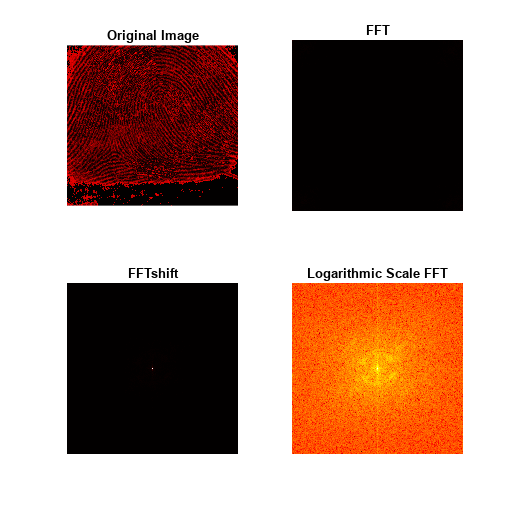

fingerprint = imread("fingerprintt.ppm");
pic = im2gray(fingerprint);
meangrayscale = mean(pic, "all");
enhanced = pic - meangrayscale;
% FFT of the pattern
Z_fft = fft2(pic);
Z_fftshift = fftshift(Z_fft);
Z_fftshift_log = log(abs(Z_fftshift) + 1);

% Plotting
figure('Position',  [200, 100, 512, 512]);
subplot(2, 2, 1); imshow(fingerprint); title('Original Image');
subplot(2, 2, 2); imagesc(abs(Z_fft)); axis square; title('FFT'); axis off;
subplot(2, 2, 3); imagesc(abs(Z_fftshift)); axis square; title('FFTshift'); axis off;
subplot(2, 2, 4); imagesc(Z_fftshift_log); axis square; title('Logarithmic Scale FFT');
axis off; colormap hot;

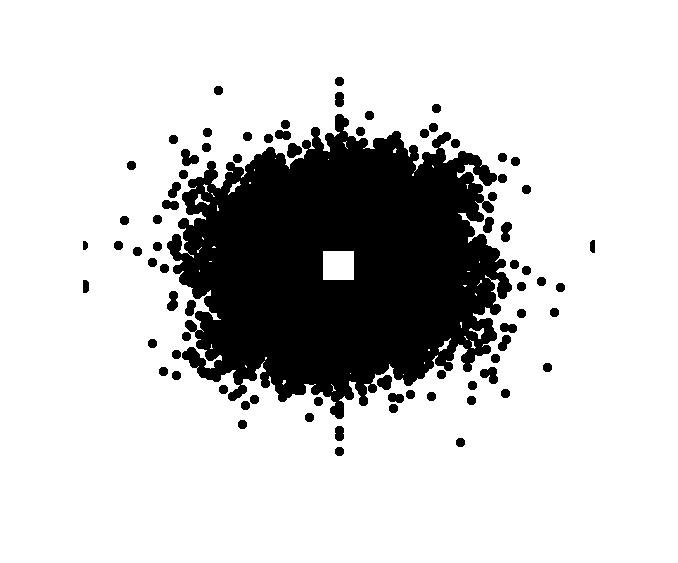

img = im2double(pic);
r = 5;
p = 0.55;

[height, width, ~] = size(img);

if numel(size(img)) == 2
    grayscale = img;
else
    grayscale = rgb2gray(img);
end

% FFT
fft = fft2(grayscale);
fft_shifted = fftshift(fft);
desired = rescale(log(abs(fft_shifted + 1)), 0, 256);

% Filtering each pixel with p% of the peak intensity
maxim = max(desired(:));
[row, column] = find(desired >= maxim * p);

% Initial value
sum = zeros(size(img));

% Initial value for ignoring the middle
ignore_row_start = round(height * 0.46);
ignore_row_end = round(height * 0.54);
ignore_col_start = round(width * 0.46);
ignore_col_end = round(width * 0.54);

% Creating a loop for the patches
for i = 1:numel(column)
    if row(i) > ignore_row_start && ...
            row(i) < ignore_row_end && ...
            column(i) > ignore_col_start && ...
            column(i) < ignore_col_end
        continue;
    end
    
    % Create circular mask
    [X, Y] = meshgrid(1:width, 1:height);
    R_circ = sqrt((X - column(i)).^2 + (Y - row(i)).^2);
    currentval = zeros(size(img));
    currentval(R_circ < r) = 1;
    
    sum = sum + currentval;
end

% Plotting
figure;
mask = imcomplement(sum);
imshow(mask);

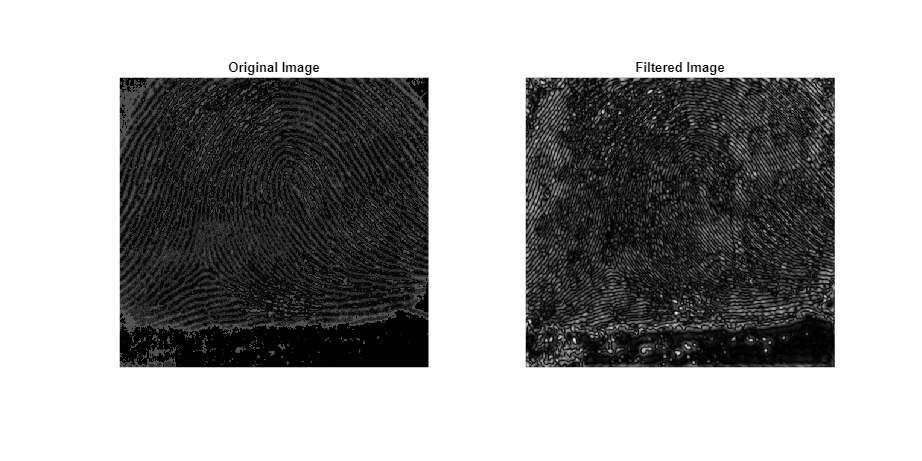

img = im2double(fingerprint);
mask_shifted = fftshift(imresize(mask, size(img)));

if numel(size(img)) == 2
    pic_fft = fft2(img);
    mult = ifft2(mask_shifted .* pic_fft);
    constructed = mult;
else
    pic_red_fft = fft2(img(:, :, 1));
    pic_green_fft = fft2(img(:, :, 2));
    pic_blue_fft = fft2(img(:, :, 3));

    mult_red = ifft2(mask_shifted .* pic_red_fft);
    mult_green = ifft2(mask_shifted .* pic_green_fft);
    mult_blue = ifft2(mask_shifted .* pic_blue_fft);

    constructed(:, :, 1) = mult_red;
    constructed(:, :, 2) = mult_green;
    constructed(:, :, 3) = mult_blue;
end
% Plotting
figure('Position', [200, 200, 1024, 512]);
subplot(1, 2, 1);
imshow(img);
title('Original Image');
subplot(1, 2, 2);
imagesc(abs(constructed));
title('Filtered Image');
axis image;
axis off; colormap gray;